% Polinomio Interpolador de LAGRANGE

% Datos del problema
x = [210, 50, 110, 30, 70];
y = [1311, 1045, 1137, 983, 1083];

% Número de puntos
n = length(x);

% Variable simbólica
syms X

% Inicializar el polinomio
L = 0;

% Construcción del polinomio de Lagrange
for i = 1:n
    li = 1;
    for j = 1:n
        if i ~= j
            li = li * (X - x(j)) / (x(i) - x(j));
        end
    end
    L = L + y(i) * li;
end

% Expandir el polinomio
L_exp = expand(L);
disp('El polinomio interpolador de Lagrange es:')

El polinomio interpolador de Lagrange es:


pretty(L_exp)

        4           3          2
    13 X      5329 X    94159 X    832919 X   77351
- -------- + -------- - -------- + -------- + -----
  12600000   10080000    1008000    100800      96



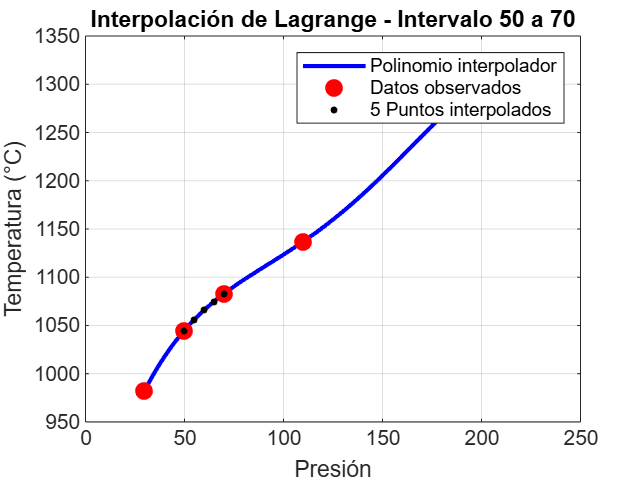


% Evaluar el polinomio en un intervalo completo
x_vals = min(x):0.4:max(x);
y_vals = double(subs(L, X, x_vals));

% Evaluar en el intervalo específico 50–70 para interpolación
x_int = 50:5:70; % pequeños puntos
y_int = double(subs(L, X, x_int));

% Graficar
figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2); hold on;
plot(x, y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot(x_int, y_int, 'k.', 'MarkerSize', 10); % puntos pequeños tipo puntico
xlabel('Presión');
ylabel('Temperatura (°C)');
title('Interpolación de Lagrange - Intervalo 50 a 70');
legend('Polinomio interpolador', 'Datos observados', '5 Puntos interpolados');
grid on;